clear; close all;


[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

FP = obj.MixedFP;
cued_this = find(obj.CueUncue==0);


bins = 0:0.001:3;
band_width = 0.1;
n_boot = 1000;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width);
kde_cdf = @(x) ksdensity(x, bins, 'Function', 'cdf', 'Bandwidth', band_width);


session_control = find(obj.Label=="Control");
session_chemo = find(obj.Label=="Chemo");
n_session = length(session_chemo);

hd_control_session = cell(n_session, 2);
hd_chemo_session = cell(n_session, 2);

hd_control = cell(1, 2);
hd_chemo = cell(1, 2);

valid = 0;
for p = 1:2
    hd_control{p} = obj.HDSortedControl{cued_this, p};
    hd_chemo{p} = obj.HDSortedChemo{cued_this, p};
    switch valid
        case 1
            hd_control{p} = hd_control{p}(hd_control{p}>0.5);
            hd_chemo{p} = hd_chemo{p}(hd_chemo{p}>0.5);
    end

    for s = 1:n_session

        hd_control_session{s, p} = obj.HDSorted{session_control(s)}{cued_this, p};
        hd_chemo_session{s, p} = obj.HDSorted{session_chemo(s)}{cued_this, p};
        switch valid
            case 1
                hd_control_session{s, p} = hd_control_session{s, p}(hd_control_session{s, p}>0.5);
                hd_chemo_session{s, p} = hd_chemo_session{s, p}(hd_chemo_session{s, p}>0.5);
        end
    end
end


pd_hd_control_session = cellfun(@(x) kde_pdf(x), hd_control_session, 'UniformOutput', false);
pd_hd_chemo_session = cellfun(@(x) kde_pdf(x), hd_chemo_session, 'UniformOutput', false);

cd_hd_control_session = cellfun(@(x) kde_cdf(x), hd_control_session, 'UniformOutput', false);
cd_hd_chemo_session = cellfun(@(x) kde_cdf(x), hd_chemo_session, 'UniformOutput', false);

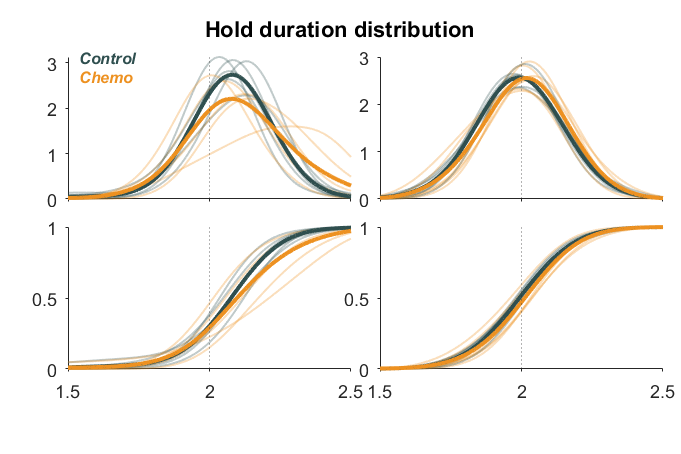

fig_hd_session = figure(34); clf(34);
set(fig_hd_session, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12 8], 'Color', 'w');

set_fig_title(fig_hd_session, 'Hold duration distribution', 'FontSize', 11);

ax = cell(2,2);

session_plot = 6;
for p = 1:2
    ax{1,p} = axes(fig_hd_session, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 4.5 5 2.5], ...
        'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    xline(ax{1,p}, FP, 'LineWidth', .5, 'LineStyle', ':');
    for s = 1:session_plot
        plot(ax{1,p}, bins, pd_hd_control_session{s, p}, ...
            'color', [GPSColor.Control .3], 'linewidth', 1, 'LineStyle', '-');
        plot(ax{1,p}, bins, pd_hd_chemo_session{s, p}, ...
            'color', [GPSColor.Treat   .3], 'linewidth', 1, 'LineStyle', '-');
    end

    pd_mean_control = mean(cell2mat(pd_hd_control_session(1:session_plot,p)), 1);
    pd_mean_chemo = mean(cell2mat(pd_hd_chemo_session(1:session_plot,p)), 1);

    plot(ax{1,p}, bins, pd_mean_control, ...
        'color', GPSColor.Control, 'linewidth', 2, 'LineStyle', '-');
    plot(ax{1,p}, bins, pd_mean_chemo, ...
        'color', GPSColor.Treat  , 'linewidth', 2, 'LineStyle', '-');

    set(ax{1,p}, 'XLim', FP + [-.5 .5], 'XTickLabel', []);

    %
    ax{2,p} = axes(fig_hd_session, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 1.5 5 2.5], ...
        'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    xline(ax{2,p}, FP, 'LineWidth', .5, 'LineStyle', ':');
    for s = 1:session_plot
        plot(ax{2,p}, bins, cd_hd_control_session{s, p}, ...
            'color', [GPSColor.Control .3], 'linewidth', 1, 'LineStyle', '-');
        plot(ax{2,p}, bins, cd_hd_chemo_session{s, p}, ...
            'color', [GPSColor.Treat   .3], 'linewidth', 1, 'LineStyle', '-');
    end

    pd_mean_control = mean(cell2mat(cd_hd_control_session(1:session_plot,p)), 1);
    pd_mean_chemo = mean(cell2mat(cd_hd_chemo_session(1:session_plot,p)), 1);

    plot(ax{2,p}, bins, pd_mean_control, ...
        'color', GPSColor.Control, 'linewidth', 2, 'LineStyle', '-');
    plot(ax{2,p}, bins, pd_mean_chemo, ...
        'color', GPSColor.Treat  , 'linewidth', 2, 'LineStyle', '-');

    set(ax{2,p}, 'XLim', FP + [-.5 .5]);

end

%
ax_legend = axes(fig_hd_session, 'Units', 'centimeters', 'Position', [ax{1,1}.Position(1)+.2 ax{1,1}.Position(2)+ax{1,1}.Position(4)-1 2 1], ...
    'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'XColor', 'none', 'YColor', 'none', 'Color', 'none', 'YDir', 'reverse');
text(ax_legend, 0, 0, '\it{Control}', 'FontSize', 8, 'FontWeight', 'bold', 'Color', GPSColor.Control);
text(ax_legend, 0, 1, '\it{Chemo}', 'FontSize', 8, 'FontWeight', 'bold', 'Color', GPSColor.Treat);
set(ax_legend, 'XLim', [0 1], 'YLim', [0 3]);

switch valid
    case 0
        fig_name = sprintf("Test_%s_Distr_Timing_session_%s.jpg", obj.Task, obj.Subject);
    case 1
        fig_name = sprintf("Test_%s_Distr_Timing_session_valid_%s.jpg", obj.Task, obj.Subject);
end
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_hd_session, fig_path, 'Resolution', 600);

pd_hd_control = cell(1, 2);
pd_hd_chemo = cell(1, 2);
pd_hd_control_ci = cell(1, 2);
pd_hd_chemo_ci = cell(1, 2);

cd_hd_control = cell(1, 2);
cd_hd_chemo = cell(1, 2);
cd_hd_control_ci = cell(1, 2);
cd_hd_chemo_ci = cell(1, 2);

for p = 1:2
    disp([p 1]);
    pd_hd_control{p} = kde_pdf(hd_control{p});
    pd_hd_chemo{p} = kde_pdf(hd_chemo{p});
    pd_hd_control_ci{p} = bootci(n_boot, {kde_pdf, hd_control{p}}, 'type', 'cper');
    pd_hd_chemo_ci{p} = bootci(n_boot, {kde_pdf, hd_chemo{p}}, 'type', 'cper');

    disp([p 2]);
    cd_hd_control{p} = kde_cdf(hd_control{p});
    cd_hd_chemo{p} = kde_cdf(hd_chemo{p});
    cd_hd_control_ci{p} = bootci(n_boot, {kde_cdf, hd_control{p}}, 'type', 'cper');
    cd_hd_chemo_ci{p} = bootci(n_boot, {kde_cdf, hd_chemo{p}}, 'type', 'cper');
end

     1     1


     1     2


     2     1


     2     2



fig = figure(34); clf(34);
set(fig, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12 11.6], 'Color', 'w');

set_fig_title(fig, 'Hold duration distribution', 'FontSize', 11);

ax = cell(3,2);

for p = 1:2
ax{1,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 7.8 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax{1,p}, FP, 'LineWidth', .5, 'LineStyle', ':');
fill(ax{1,p}, [bins flip(bins)], [pd_hd_control_ci{p}(1,:) flip(pd_hd_control_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
p1 = plot(ax{1,p}, bins, pd_hd_control{p}, ...
    'color', GPSColor.Control, 'linewidth', 1, 'LineStyle', '-');
fill(ax{1,p}, [bins flip(bins)], [pd_hd_chemo_ci{p}(1,:) flip(pd_hd_chemo_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
p2 = plot(ax{1,p}, bins, pd_hd_chemo{p}, ...
    'color', GPSColor.Treat  , 'linewidth', 1, 'LineStyle', '-');

ax{2,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 4.5 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax{2,p}, FP, 'LineWidth', .5, 'LineStyle', ':');
fill(ax{2,p}, [bins flip(bins)], [cd_hd_control_ci{p}(1,:) flip(cd_hd_control_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
plot(ax{2,p}, bins, cd_hd_control{p}, ...
    'color', GPSColor.Control, 'linewidth', 1, 'LineStyle', '-');
fill(ax{2,p}, [bins flip(bins)], [cd_hd_chemo_ci{p}(1,:) flip(cd_hd_chemo_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
plot(ax{2,p}, bins, cd_hd_chemo{p}, ...
    'color', GPSColor.Treat  , 'linewidth', 1, 'LineStyle', '-');

ax{3,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 1.2 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax{3,p}, FP, 'LineWidth', .5, 'LineStyle', ':');

hd_this_control = hd_control{p}(randperm(length(hd_control{p}), 100));
hd_this_chemo = hd_chemo{p}(randperm(length(hd_chemo{p}), 100));
hd_this = [hd_this_control; hd_this_chemo];
c_this = [repmat(GPSColor.Control, 100, 1); repmat(GPSColor.Treat, 100, 1)];
t_this = [1:100 1:100]';

id_perm = randperm(200);
hd_perm = hd_this(id_perm);
c_perm = c_this(id_perm, :);
t_perm = t_this(id_perm);

scatter(ax{3,p}, hd_perm, t_perm, 12, c_perm, ...
    'MarkerEdgeColor', 'flat', 'MarkerEdgeAlpha', 0.6, 'LineWidth', 1, ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', 0.6);

for a = 1:3
    set(ax{a,p}, 'XLim', FP + [-1 1]);

    if p==2
        ax{a,p}.YTickLabel = [];
    end
    if a<3
        ax{a,p}.XTickLabel = [];
    else
        ax{a,p}.XLabel.String = "Hold duration (s)";
        ax{a,p}.XLabel.FontWeight = "bold";
    end
end

end

%
ax_legend = axes(fig, 'Units', 'centimeters', 'Position', [ax{1,1}.Position(1)+.2 ax{1,1}.Position(2)+ax{1,1}.Position(4)-1 2 1], ...
    'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'XColor', 'none', 'YColor', 'none', 'Color', 'none', 'YDir', 'reverse');
text(ax_legend, 0, 0, '\it{Control}', 'FontSize', 8, 'FontWeight', 'bold', 'Color', GPSColor.Control);
text(ax_legend, 0, 1, '\it{Chemo}', 'FontSize', 8, 'FontWeight', 'bold', 'Color', GPSColor.Treat);
set(ax_legend, 'XLim', [0 1], 'YLim', [0 3]);

%
ax{1,1}.YLim(2) = max([ax{1,1}.YLim(2) ax{1,2}.YLim(2)]);
ax{1,1}.YLim(2) = .5 * (ceil(ax{1,1}.YLim(2)) + round(ax{1,1}.YLim(2)));
ax{1,2}.YLim(2) = ax{1,1}.YLim(2);

%
ax{1,1}.YLabel.String = "Prob. density (1/s)";
ax{1,1}.YLabel.FontWeight = "bold";

ax{2,1}.YLabel.String = "Cumulative distr.";
ax{2,1}.YLabel.FontWeight = "bold";

ax{3,1}.YLabel.String = "Trials";
ax{3,1}.YLabel.FontWeight = "bold";

%
ax{1,1}.Title.String = "Left";
ax{1,1}.Title.Color = GPSColor.PortL;
ax{1,1}.Title.FontWeight = "bold";

ax{1,2}.Title.String = "Right";
ax{1,2}.Title.Color = GPSColor.PortR;
ax{1,2}.Title.FontWeight = "bold";

switch valid
    case 0
        fig_name = sprintf("Test_%s_Distr_Timing_%s.jpg", obj.Task, obj.Subject);
    case 1
        fig_name = sprintf("Test_%s_Distr_Timing_valid_%s.jpg", obj.Task, obj.Subject);
end
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);
